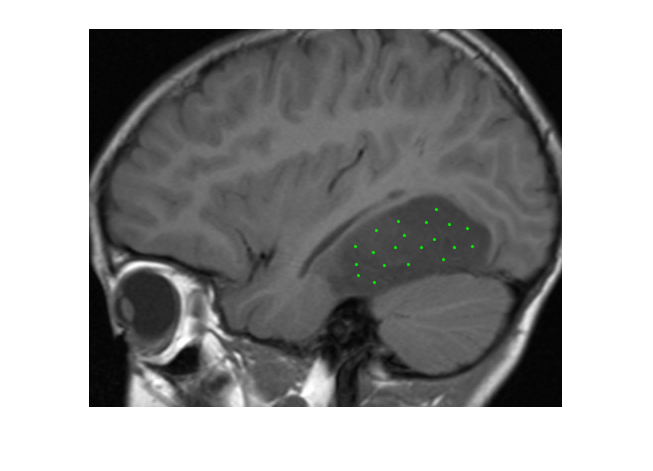

%Load dataset
Im = load("tumorData.mat");
Im = Im.data;
%Load selected tumor points
SelPoints = cell2mat(struct2cell(load("SelPoints.mat"))');
xSelPoints = round(SelPoints(:, 1));
ySelPoints = round(SelPoints(:, 2));
%Visualize the selected points 
figure();
imshow(Im, [])
hold on;
plot(xSelPoints, ySelPoints, '.g')
hold off;

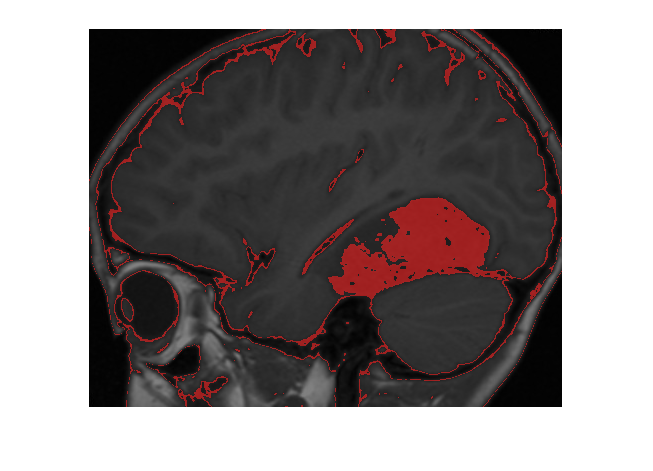

%Calculate the mean and standard deviation of the intensities of selected points
ImSelIntensity = diag(Im(ySelPoints, xSelPoints));
tumorMean = mean(ImSelIntensity);
tumorStd = var(ImSelIntensity);
%Calculate the mean and standard deviation of all image intensities
ImMean = mean(Im(:));
ImStd = var(Im(:));

%Define the prior probabilities
pi = [0.2 0.8];

%Calculate posterior probabilities
posteriorLab1 = normpdf(Im, tumorMean, sqrt(tumorStd)) * pi(1) ./ (normpdf(Im, tumorMean, sqrt(tumorStd)) * pi(1) ...
    + normpdf(Im, ImMean, sqrt(ImStd)) * pi(2));

%Since there are only 2 classes, the posterior probability of the 2nd class
%can be calculates as 1 - P
posteriorLab2 = 1 - posteriorLab1;
rgb = zeros([size(Im) 3]);
rgb(:, :, 1) = posteriorLab1 > posteriorLab2;
ImFused = imfuse(Im, rgb, 'blend');
imshow(ImFused)


% se1 = strel("diamond", 6);
% se2 = strel("square", 2);
% rgb = imclose(rgb, se2);
% rgb = imopen(rgb, se1);
% rgb = imclose(rgb, se1);
